sourceImg=ones(128);
A=sourceImg*0.5;
targetSize = [20 20];
win1 = centerCropWindow2d(size(A),targetSize);
B=zeros(128);
B(win1.XLimits(1):win1.XLimits(2),win1.YLimits(1):win1.YLimits(2))=1;
D=0:1/127:1;
C=sourceImg.*D;
targetSize = [1 1];
win1 = centerCropWindow2d(size(A),targetSize);
D=zeros(128);
D(win1.XLimits(1),win1.YLimits(1))=1;

x=cos(2*pi*((0:127)/(128/4)));
y=cos(2*pi*((0:127)/(128/4)));
[X,Y] = meshgrid(x,y);
E=(X+Y)/2;

disp("A")

A


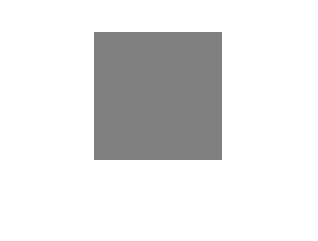

imshow(A)

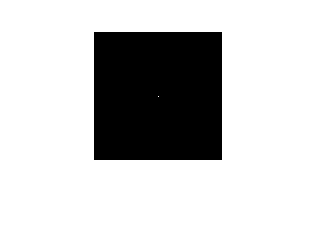

makeDFT(A)


disp("B")

B


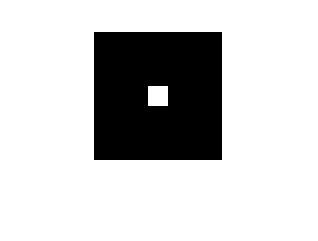

imshow(B)

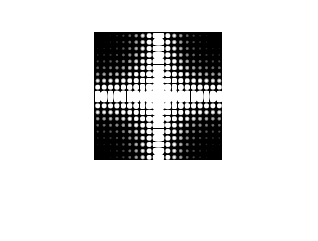

makeDFT(B)


disp("C")

C


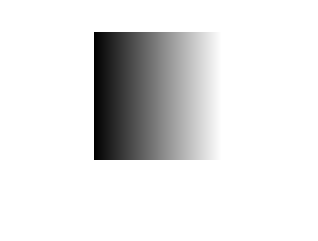

imshow(C)

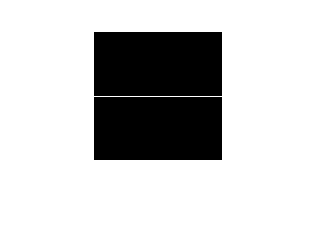

makeDFT(C)


disp("D")

D


imshow(D)

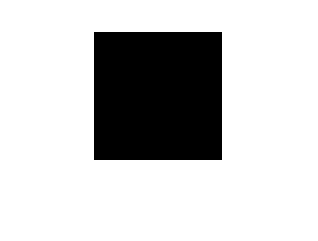

makeDFT(D)


disp("E")

E


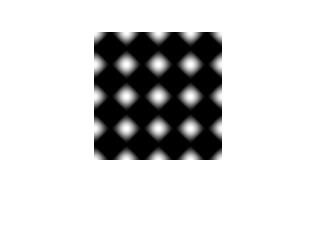

imshow(E)

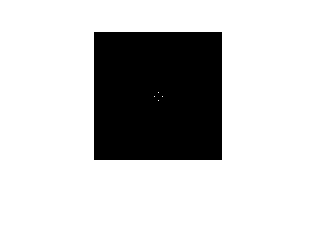

makeDFT(E)

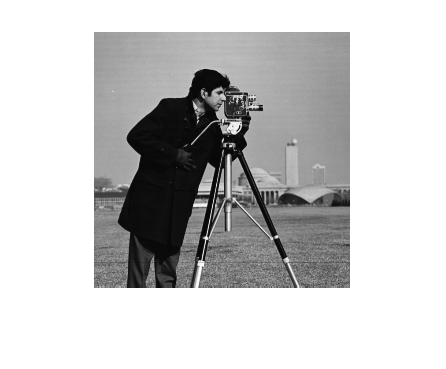

Img=imread('cameraman.tif');
figure()
imshow(Img)

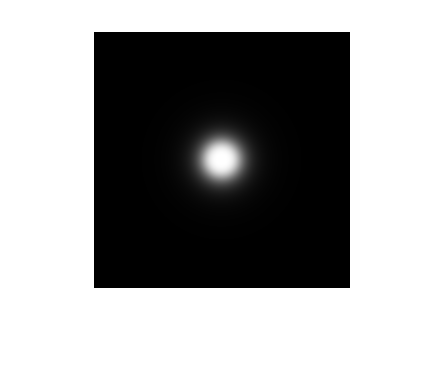

D0=20;
n=2;
[H,H1]=BWLPfilter(Img,D0,n);
F = fft2(double(Img));
Fc = fftshift(F);
G = H.*Fc;
gi = ifft2(ifftshift(G));
g = real(gi);

G1 = H1.*Fc;
gi1 = ifft2(ifftshift(G1));
g1 = real(gi1);

figure()
imshow(H)

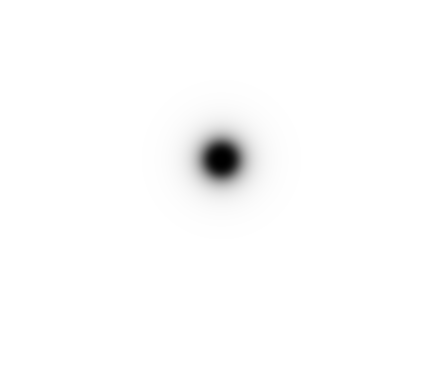


figure()
imshow(H1)

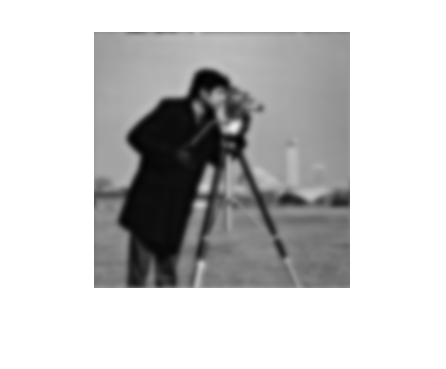


figure()
imshow(uint8(g))

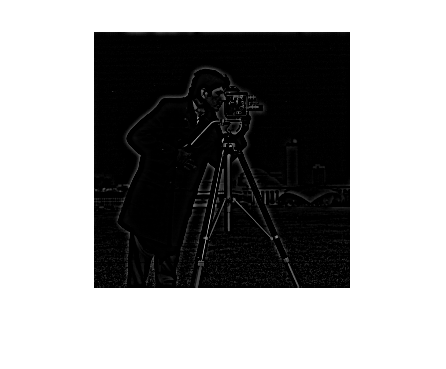


figure()
imshow(uint8(g1))

function makeDFT(I)
    F = fft2(I);
    Fc = fftshift(F);
    imshow(log(abs(Fc) + 0.0001));
    H=ones(size(I));
    G = H.*Fc;
    gi = ifft2(ifftshift(G));
    g = real(gi);
end